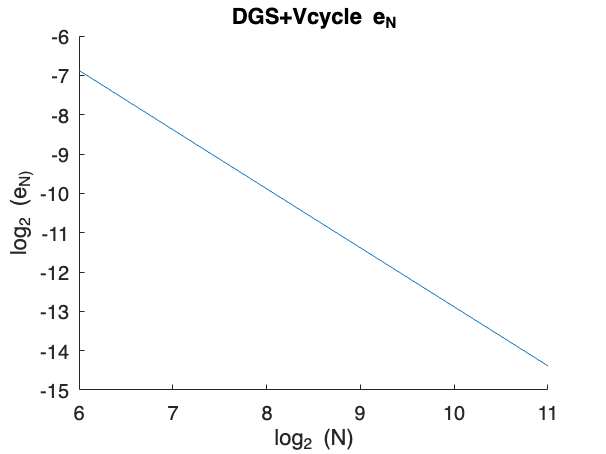

%测试DGS+Vcycle
addpath("test_func", "up_down_operator");
Nset = [64; 128; 256; 512; 1024; 2048];
err = zeros(length(Nset), 1);
t = zeros(length(Nset), 1);
stp = zeros(length(Nset), 1);
for i = 1: length(Nset)
    tic;
    N = Nset(i);
    para = get_para(N);
    [poi, stp(i)] = Vcycle_DGS(para);
    err(i) = err_std(poi, para);
    t(i) = toc;
end
figure;
hold on;
plot(log(Nset)/log(2), log(err)/log(2));
title("DGS+Vcycle e_N");
xlabel("log_2 (N)");
ylabel("log_2 (e_N)");
hold off;

Names = {'N'; 'time'; 'e_N'; 'steps'};
T = table(Nset, t, err, stp, ...
    'VariableNames',Names)

T = 6×4 table
     N       time         e_N        steps
    ____    _______    __________    _____

      64    0.11506     0.0085233     18  
     128    0.46177     0.0030007     18  
     256     1.8105     0.0010587     17  
     512     7.7597    0.00037394     17  
    1024      49.59    0.00013213     17  
    2048     245.25    4.6683e-05     17  


table2latex(T, 'table.tex')

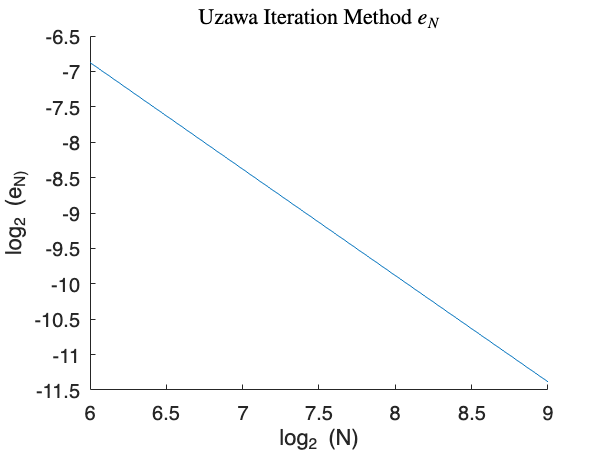

%测试Uzawa
addpath("test_func", "up_down_operator");
Nset = [64; 128; 256; 512];
err = zeros(length(Nset), 1);
t = zeros(length(Nset), 1);
stp = zeros(length(Nset), 1);
for i = 1: length(Nset)
    tic;
    N = Nset(i);
    para = get_para(N);
    [poi, stp(i)] = UIM(para);
    err(i) = err_std(poi, para);
    t(i) = toc;
end
figure;
hold on;
plot(log(Nset)/log(2), log(err)/log(2));
title("Uzawa Iteration Method $e_N$", ...
    'interpreter', 'latex');
xlabel("log_2 (N)");
ylabel("log_2 (e_N)");
hold off;

Names = {'N'; 'time'; 'e_N'; 'steps'};
T = table(Nset, t, err, stp, ...
    'VariableNames',Names)

T = 4×4 table
     N      time         e_N        steps
    ___    _______    __________    _____

     64    0.11057     0.0085233     21  
    128    0.53427     0.0030007     36  
    256     4.8315     0.0010587     59  
    512     29.011    0.00037395     55  


table2latex(T, 'table.tex')

%测试Inexact Uzawa
addpath("test_func", "up_down_operator");
Nset = [64; 128; 256; 512; 1024; 2048];
err = zeros(length(Nset), 1);
t = zeros(length(Nset), 1);
stp = zeros(length(Nset), 1);
for i = 1: length(Nset)
    tic;
    N = Nset(i);
    para = get_para(N);
    [poi, stp(i)] = IUIM(para);
    err(i) = err_std(poi, para);
    t(i) = toc;
end
figure;
hold on;
plot(log(Nset)/log(2), log(err)/log(2));
title("Inexact Uzawa Iteration Method $e_N$", ...
    'interpreter', 'latex');
xlabel("log_2 (N)");
ylabel("log_2 (e_N)");
hold off;
Names = {'N'; 'time'; 'e_N'; 'steps'};
T = table(Nset, t, err, stp, ...
    'VariableNames',Names)

T = 6×4 table
     N        time         e_N        steps
    ____    ________    __________    _____

      64    0.073781     0.0085233      4  
     128     0.23805     0.0030007      4  
     256     0.94202     0.0010587      4  
     512      4.0674    0.00037395      4  
    1024      23.824    0.00013212      4  
    2048      128.96    4.6674e-05      4  


table2latex(T, 'table.tex')